---

title: "PEP_wp4_beh"

output: html_document

date: "2023-12-15"

--- house keeping ---

% clear workspace
clear;
clc;

% set working directory
wd = 'C:/Users/JLU-SU/OneDrive - Justus-Liebig-Universität Gießen/Dokumente/GitHub/pep_wp4_analysis';
cd(wd);

function_folder = fullfile(pwd, 'functions')

function_folder = 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_analysis\functions'

addpath(function_folder)

--- loading files ---

% details of subjects
d.subNums = [101:106,109:127,129:141]; 
d.n = length(d.subNums);

% add scene categories
d.categories = {'bathroom', 'kitchen'};

% load files using costum function
d = load_files(d);

Loaded: 101
Loaded: 102
Loaded: 103
Loaded: 104
Loaded: 105
Loaded: 106
Loaded: 109
Loaded: 110
Loaded: 111
Loaded: 112
Loaded: 113
Loaded: 114
Loaded: 115
Loaded: 116
Loaded: 117
Loaded: 118
Loaded: 119
Loaded: 120
Loaded: 121
Loaded: 122
Loaded: 123
Loaded: 124
Loaded: 125
Loaded: 126
Loaded: 127
Loaded: 129
Loaded: 130
Loaded: 131
Loaded: 132
Loaded: 133
Loaded: 134
Loaded: 135
Loaded: 136
Loaded: 139
Loaded: 140


--- simulate additional subjects ---

% % based on each subject, how many additional subjects should be simulated
% sim_para.sim_subs = 10;
% 
% % Set parameters
% sim_para.RT_sd = 0.3;
% sim_para.acc_sd = 0.5;
% sim_para.rating_sd = 0.8;
% sim_para.baseline_sd = 0.2;
% 
% % use costum function to simulate data 
% d = sim_additional_subs(d, sim_para);

--- timing ----

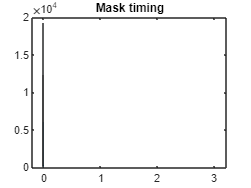

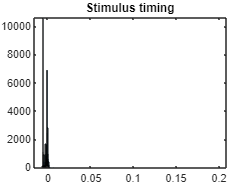

Timin is calculated


% call costum function to calculate and plot the timing
[timing, d]  = calculate_timing(d);

--- transfrom data (and trial and subject exclusion) ---

% make trial exclusion using a costum function 
d = trial_exclusion(d);

0 trials were < 0.1 s
353 trials were > 3 s
4 trials displayed stimulus on wrong frame
9 trials displayed mask on wrong frame
361 trials have been excluded
This equals 0.0058452 % of all trials



% transform data using a costum function (adds a couple new subtables)
d = transform_data(d);

Data transformation has been performed




% make subject exclusion using a costum function 
d = subject_exclusion(d);

Subject 101 meets all inclusion criteria
Subject 102 meets all inclusion criteria
Subject 103 meets all inclusion criteria
Subject 104 meets all inclusion criteria
Subject 105 meets all inclusion criteria
Subject 106 meets all inclusion criteria
Subject 109 meets all inclusion criteria


Subject 111 meets all inclusion criteria
Subject 112 meets all inclusion criteria
Subject 113 meets all inclusion criteria
Subject 114 meets all inclusion criteria
Subject 115 meets all inclusion criteria
Subject 116 meets all inclusion criteria
Subject 117 meets all inclusion criteria
Subject 118 meets all inclusion criteria
Subject 119 meets all inclusion criteria
Subject 120 meets all inclusion criteria
Subject 121 meets all inclusion criteria
Subject 122 meets all inclusion criteria
Subject 123 meets all inclusion criteria
Subject 124 meets all inclusion criteria
Subject 125 meets all inclusion criteria
Subject 126 meets all inclusion criteria
Subject 127 meets all inclusion criteria
Subject 129 meets all inclusion criteria
Subject 130 meets all inclusion criteria
Subject 131 meets all inclusion criteria
Subject 132 meets all inclusion criteria


Subject 134 meets all inclusion criteria
Subject 135 meets all inclusion criteria
Subject 136 meets all inclusion criteria
Subject 139 meets all inclusion criteria
Subject 140 meets all inclusion criteria
Data transformation is repeated because of subject exclusion
Data transformation has been performed




% make a backup of d
d2 = d;

%% CHECK If RATING ARE CORRECT

--- performance --- 

% call a costum function to calculate performance
perf = make_perf(d);

Performance is calculated
Mean accuracy: 0.65723
Mean RT: 0.8428



--- HISTOGRAMS ---

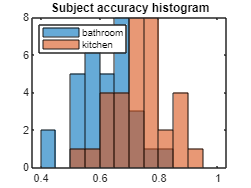

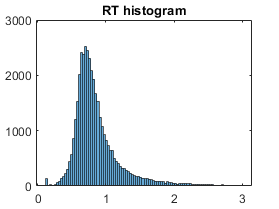

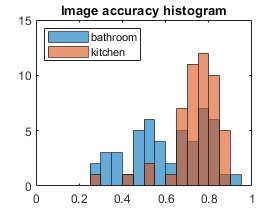

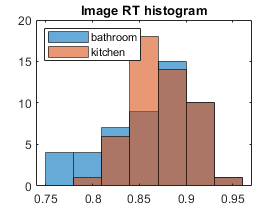

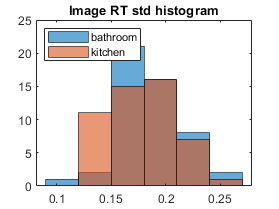

% call a costum function to plot histograms
hist_plots = hist_plots(d);

--- Simulation of img_id_table (only for testing purpose!)

% n_imgs = 50;
% mode = 'dependent';
% variables_of_interest = {'mean_RT','mean_trial_accuracy', 'mean_neg_RT', 'IES', 'typicality','familiarity','aesthetic','usability','complexity'};
% target_r = [-0.7, 0.8, 0.7, -0.8, 1, 0.9, 0.1, 0.1, -0.2];
% 
% % simulate new img_id_table data
% simulated_img_id_table = sim_img_id_table(mode, d.subNums, n_imgs, variables_of_interest, target_r);
% 
% d.original_img_id_table = d.img_id_table;
% d.img_id_table = simulated_img_id_table; % CAUTION: overwrites actual data with simulated data! 

--- rating correlation ---

Plotting and saving correlation plot for inter-subject level - bathroom


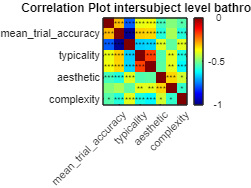

Plotting and saving correlation plot for inter-subject level - kitchen


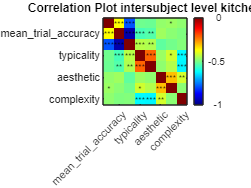

Plotting and saving correlation plot for own vs other analysis on task correaltions - bathroom


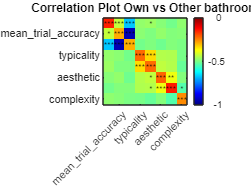

Plotting and saving correlation plot for own vs other analysis on task correaltions - kitchen


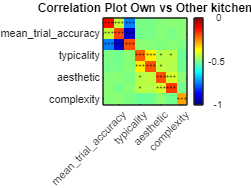

% call a costum function to calculate and plot the correlations of rating on
% population level
[rating_cor_plots, d] = plot_rating_cor(d);

--- intersubject correaltions ---

Plotting and saving inter-subject RDM for task:mean_trial_accuracy and bathroom


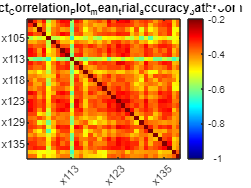

Plotting and saving inter-subject MDS for task: mean_trial_accuracy and bathroom


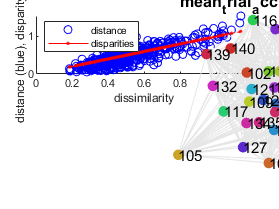

Plotting and saving inter-subject RDM for task:mean_neg_RT and bathroom


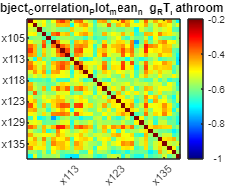

Plotting and saving inter-subject MDS for task: mean_neg_RT and bathroom


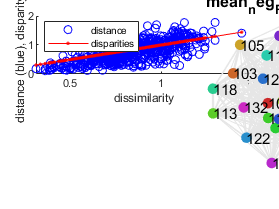

Plotting and saving inter-subject RDM for task:IES and bathroom


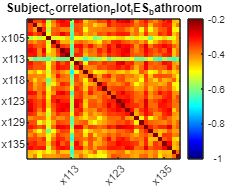

Plotting and saving inter-subject MDS for task: IES and bathroom


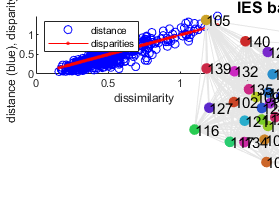

Plotting and saving inter-subject RDM for task:typicality and bathroom


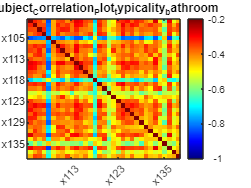

Plotting and saving inter-subject MDS for task: typicality and bathroom


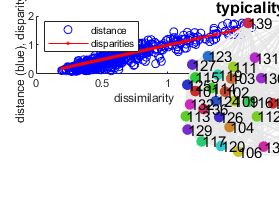

Plotting and saving inter-subject RDM for task:familiarity and bathroom


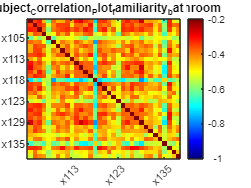

Plotting and saving inter-subject MDS for task: familiarity and bathroom


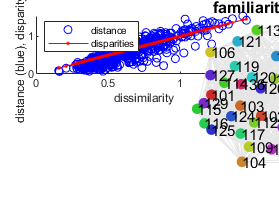

Plotting and saving inter-subject RDM for task:aesthetic and bathroom


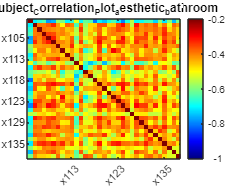

Plotting and saving inter-subject MDS for task: aesthetic and bathroom


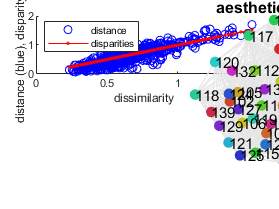

Plotting and saving inter-subject RDM for task:usability and bathroom


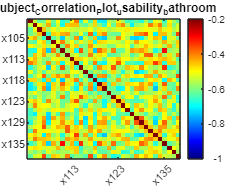

Plotting and saving inter-subject MDS for task: usability and bathroom


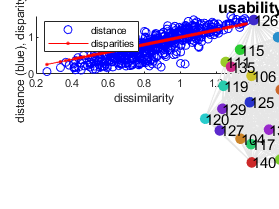

Plotting and saving inter-subject RDM for task:complexity and bathroom


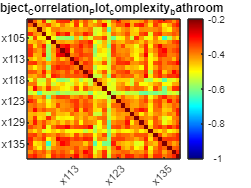

Plotting and saving inter-subject MDS for task: complexity and bathroom


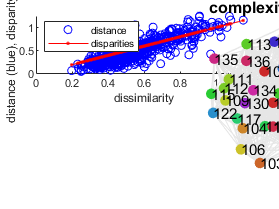

Plotting and saving inter-subject RDM for task:mean_trial_accuracy and kitchen


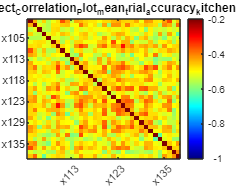

Plotting and saving inter-subject MDS for task: mean_trial_accuracy and kitchen
Plotting and saving inter-subject RDM for task:mean_neg_RT and kitchen


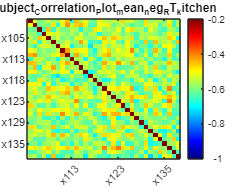

Plotting and saving inter-subject MDS for task: mean_neg_RT and kitchen


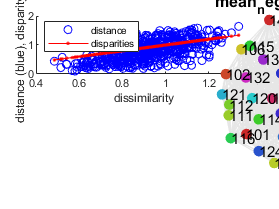

Plotting and saving inter-subject RDM for task:IES and kitchen


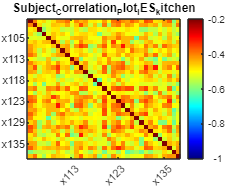

Plotting and saving inter-subject MDS for task: IES and kitchen


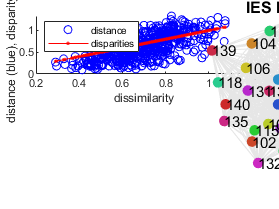

Plotting and saving inter-subject RDM for task:typicality and kitchen


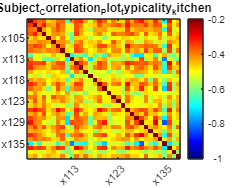

Plotting and saving inter-subject MDS for task: typicality and kitchen


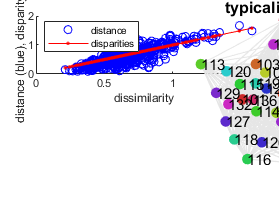

Plotting and saving inter-subject RDM for task:familiarity and kitchen


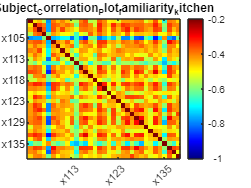

Plotting and saving inter-subject MDS for task: familiarity and kitchen


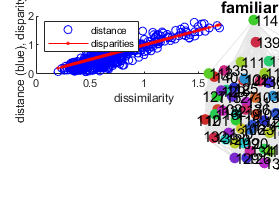

Plotting and saving inter-subject RDM for task:aesthetic and kitchen


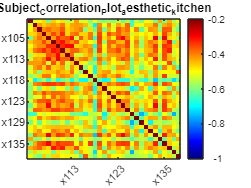

Plotting and saving inter-subject MDS for task: aesthetic and kitchen


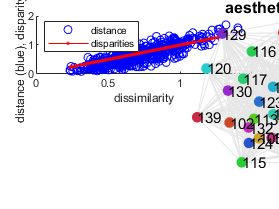

Plotting and saving inter-subject RDM for task:usability and kitchen


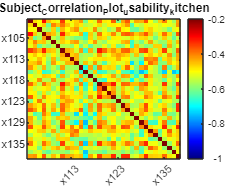

Plotting and saving inter-subject MDS for task: usability and kitchen


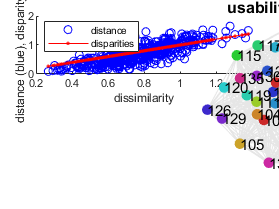

Plotting and saving inter-subject RDM for task:complexity and kitchen


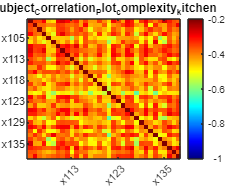

Plotting and saving inter-subject MDS for task: complexity and kitchen


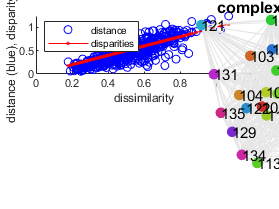

Compare categories


% call a costum function to calculate and plot the correlations of rating between subjects
[cor_plots, d] = intersub_cor(d);

--- task correaltions ---

% call a costum function to calculate and plot the correlations between task RDMs
[cor_plots, d] = RDM_of_RDMs(cor_plots, d);

--- combine all measures ---

% call a costum function that combines all measures/tasks
% [cor_plots, d]  = combined(cor_plots, d);
% d = make_mean_RDM(d);

--- correlate photos with DNN layer --- 

Loaded image: 101_bat1.png
Loaded image: 101_bat2.png
Loaded image: 102_bat1.png
Loaded image: 102_bat2.png
Loaded image: 103_bat.png
Loaded image: 104_bat.png
Loaded image: 105_bat1.png
Loaded image: 105_bat2.png
Loaded image: 106_bat1.png
Loaded image: 106_bat2.png
Loaded image: 109_bat.png
Loaded image: 111_bat.png
Loaded image: 112_bat.png
Loaded image: 113_bat1.png
Loaded image: 113_bat2.png
Loaded image: 114_bat.png
Loaded image: 115_bat.png
Loaded image: 116_bat.png
Loaded image: 117_bat.png
Loaded image: 118_bat1.png
Loaded image: 118_bat2.png
Loaded image: 119_bat.png
Loaded image: 120_bat.png
Loaded image: 121_bat.png
Loaded image: 122_bat1.png
Loaded image: 122_bat2.png
Loaded image: 123_bat1.png
Loaded image: 123_bat2.png
Loaded image: 124_bat.png
Loaded image: 125_bat.png
Loaded image: 126_bat.png
Loaded image: 127_bat.png
Loaded image: 129_bat1.png
Loaded image: 129_bat2.png
Loaded image: 130_bat1.png
Loaded image: 130_bat2.png
Loaded image: 131_bat1.png
Loaded image: 131

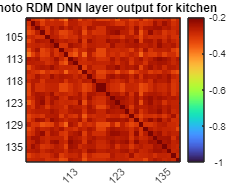

% correlate photos with DNN layer
d = extract_dnn_similarities_googlenet_func(d, 0);

Plotting correaltion of DNN layer representation of photos with intersubject RDM for bathroom


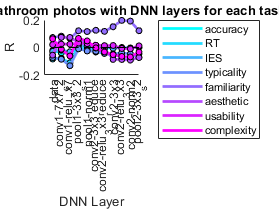

Plotting correaltion of DNN layer representation of photos with intersubject RDM for kitchen


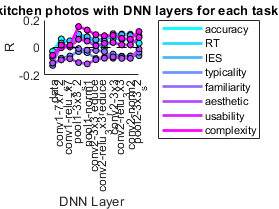


% correlate similarities between subs with intersubject RDMs for each task
plot_dnn_cor_photos(d);

% pca(x, 'NumComponents',1)

% userOptions.RDMcorrelationType='Kendall_taua';
% userOptions.RDMrelatednessTest = 'subjectRFXsignedRank';
% userOptions.RDMrelatednessThreshold = 0.05;
% userOptions.RDMrelatednessMultipleTesting = 'FDR';
% userOptions.saveFiguresPDF = 1;
% userOptions.candRDMdifferencesTest = 'subjectRFXsignedRank';
% userOptions.candRDMdifferencesThreshold = 0.05;
% userOptions.candRDMdifferencesMultipleTesting = 'FDR';
% userOptions.plotpValues = '=';
% userOptions.barsOrderedByRDMCorr=true;
% userOptions.resultsPath = userOptions.rootPath;
% userOptions.figureIndex = [14 15];
% userOptions.figure1filename = 'compareRefRDM2candRDMs_barGraph_simulatedITasRef';
% userOptions.figure2filename = 'compareRefRDM2candRDMs_pValues_simulatedITasRef';

% pss = rsa.compareRefRDM2candRDMs(ref_RDM, candRDMs, userOptions);
